% Show that series
% u(x,n)=(sin(x)+3^(1/3)*cos(x))^n/3^n
% converges in the interval (-inf;+inf)
% and establish the character of convergence.

clear
syms x n;
u(x,n)=sym((sin(x)+3^(1/2)*cos(x))^n/3^n)

$$u(x, n) = \frac{{\left(\sin\left(x\right)+\sqrt{3}\,\cos\left(x\right)\right)}^{n}}{3^{n}}$$


% u(x,n) < (1+3^(1/2))^n/3^n
u1(n)=sym((1+3^(1/2))^n/3^n)

$$u1(n) = \frac{{\left(\frac{6152031499462229}{2251799813685248}\right)}^{n}}{3^{n}}$$

% 0.9107^n
L=limit(u1,n,inf)

$$L = 0$$

% 0 =>  series u(x,n) converges

d(x,n)=simplify(u(x,n+1)/u(x,n))

$$d(x, n) = \frac{2\,\sin\left(x+\frac{\pi }{3}\right)}{3}$$

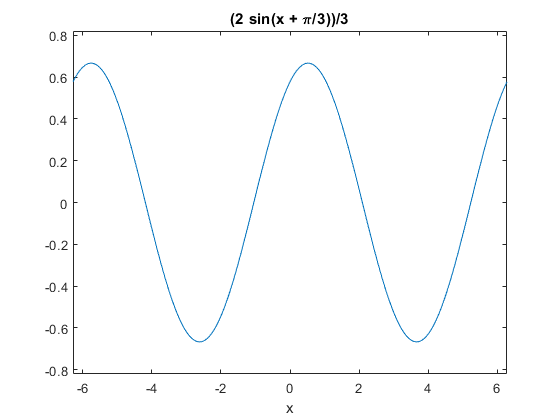

% sin(x)/3 + (3^(1/2)*cos(x))/3

% d(x,n) < 1/3+3^(1/2)/3 = 0.9107 < 1 => 
%  series converges at (-inf;+inf)

ezplot(d(x,n))

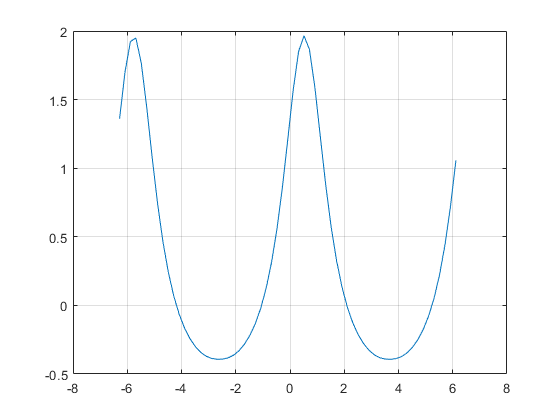


syms i;
x1=-2*pi:0.2:2*pi;
s=zeros(1,length(x1));
for i=1:10
    s=s+u(x1,i);
    plot(x1,s)
    grid on
end
hold off

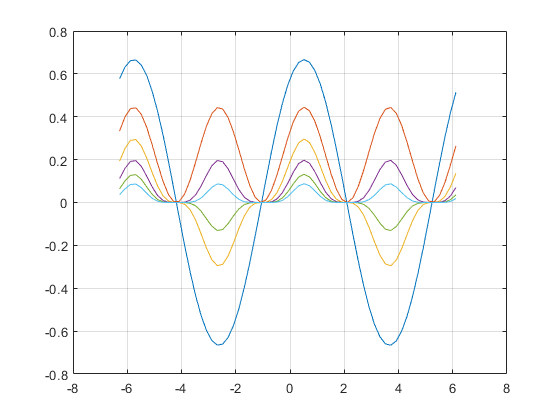


syms i;
x1=-2*pi:0.2:2*pi;
for i=1:6
    y1=u(x1,i);
    plot(x1,y1)
    hold on
    grid on
end
hold off